Homework 4

Shaobo Wang

Problem 1

clear;clc

Q(a)


$$A = \left[\matrix{0&1\cr 3&-2}\right], B= \left[\matrix{0&1\cr 3&0}\right]$$
 

A = [0,1;3,-2];
B = [0,1;3,0];

Spectral radius is the largest magnitute of eigenvalues:

Let $\det(A-\lambda I) = \det( \left[\matrix{-\lambda&1\cr 3&-2-\lambda}\right]) = 0 \Rightarrow 
\begin{cases}
\lambda_1 = -3\\
\lambda_2 = 1
\end{cases}
\Rightarrow \rho(A) = 3$ 

Let $\det(B-\lambda I) = \det( \left[\matrix{-\lambda&1\cr 3&-\lambda}\right]) = 0 \Rightarrow 
\begin{cases}
\lambda_1 = -\sqrt3\\
\lambda_2 = \sqrt3
\end{cases}
\Rightarrow
\rho(B) = \sqrt3$ 

Check with MATLAB commands:

sr_A = max(abs(eig(A)))

sr_A = 3

sr_B = max(abs(eig(B)))

sr_B = 1.7321

Frobenius norm:


$$\|A\|_F = \sqrt{\sum_{i,j}|a_{ij}|^2}=\sqrt{0+1^2+3^2+2^2}=\sqrt{14}$$
 


$$\|B\|_F = \sqrt{\sum_{i,j}|b_{ij}|^2}=\sqrt{0+1^2+3^2+0}=\sqrt{10}$$
  

Check with MATLAB commands:

Nfro_A = norm(A,'fro')

Nfro_A = 3.7417

Nfro_B = norm(B,'fro')

Nfro_B = 3.1623

The 1-norm:


$$\|A\|_1 = \max_{j}(\sum_{i}|a_{ij}|)= \max(3,3)=3$$



$$\|B\|_1 = \max_{j}(\sum_{i}|b_{ij}|)= \max(3,1)=3$$


Check with MATLAB commands:

N1_A = norm(A,1)

N1_A = 3

N1_B = norm(B,1)

N1_B = 3

The 2-norm:

$\|A\|_2 = \bar\sigma(A)$:

sigbar_A = max(svd(A))

sigbar_A = 3.6503

sigbar_A_ = sqrt(max(abs(eig(conj(A)'*A))))

sigbar_A_ = 3.6503

$\|B\|_2 = \bar\sigma(B)$:

sigbar_B = max(svd(B))

sigbar_B = 3

sigbar_B_ = sqrt(max(abs(eig(conj(B)'*B))))

sigbar_B_ = 3

Check with MATLAB commands:

N2_A = norm(A)

N2_A = 3.6503

N2_B = norm(B)

N2_B = 3

The $\infty$-norm:


$$\|A\|_{\infty} = \max_{i}(\sum_{j}|a_{ij}|)= \max(1,5)=5$$



$$\|B\|_{\infty} = \max_{i}(\sum_{j}|b_{ij}|)= \max(1,3)=3$$


Check with MATLAB commands:

Ninf_A = norm(A,'inf')

Ninf_A = 5

Ninf_B = norm(B,'inf')

Ninf_B = 3

Q(b)

Proof $\|A\|_{max} = \max_{i,j}|a_{ij}|$ is a generalized matrix norm:

Property 1: $\forall i,j\ \|A\|_{max} \geq |a_{ij}|\geq0$ 

Property 2: $\begin{cases}
A = 0\Rightarrow \forall i,j\ |a_{ij}|=0 \Rightarrow \|A\|_{max}=0\\
\|A\|_{max} = 0\Rightarrow \forall i,j\ |a_{ij}|\leq 0\Rightarrow \forall i,j\ |a_{ij}| = 0\Rightarrow A=0
\end{cases}$ 

Property 3: $\|\alpha A\|_{max} = \max_{i,j}|\alpha\cdot a_{ij}| = |\alpha|\cdot \max_{i,j}|a_{ij}| = |\alpha|\|A\|_{max}$ 

Property 4: $\|A+B\|_{max} =  \max_{i,j}|a_{ij}+b_{ij}| \leq \max_{ij} |a_{ij}|+\max_{ij} |b_{ij}| = \|A\|_{max}+\|B\|_{max}$

Counterexamples:

$\|A\|_{max} < \rho(A)$ : e.g. $A = \left[\matrix{1&1\cr0&0}\right], \|A\|_{max} = 1, \rho(A) = \sqrt{2}$ 

$\|AB\|_{max} > \|A\|_{max}\|B\|_{max}$ : e.g. $A = \left[\matrix{1&1\cr0&0}\right], B = \left[\matrix{1&0\cr1&0}\right],\|AB\|_{max} = 2, \|A\|_{max}\|B\|_{max} = 1$ 

Q(c) 

For a SISO system, the transfer function G is a scalar:

$\|G\|_2 = \sqrt{\frac{1}{2\pi}\int_{-\infty}^{\infty}|G(j\omega)|^2d\omega}$ and $\|G\|_{\infty} = \max_{\omega} |G(j\omega)|$ .

For $Q = e^{-sT}$ or $Q = \frac{s-a}{s+a}$, $|Q(j\omega)| = 1$ , $|QG(j\omega)|=|Q(j\omega)||G(j\omega)|=|G(j\omega)|$ .

Therefore, 

$\|G\|_2 = \|QG\|_2$ and $\|G\|_{\infty}= \|QG\|_{\infty}$ 

Test with numerical example:

s = tf('s');
T = 10;
G = (s+1)/(s+2)/(s+3);
Q1 = exp(-s*T);
Q2 = (s-3)/(s+3);

$\infty
$-norm:

Ninf_G = [norm(G,'inf');norm(Q1*G,'inf');norm(Q2*G,'inf')]

Ninf_G =     0.2193
    0.2193
    0.2193


2-norm:

N2_G =[norm(G,2);norm(Q1*G,2);norm(Q2*G,2)]

N2_G =     0.3416
    0.3416
    0.3416


Problem 2

clear;clc

DIDO systetransfer function:

s = tf('s');
G = [10*(s+2)/(s^2+0.2*s+100), 1/(s+5); 
    (s+2)/(s^2+0.1*s+10), 5*(s+1)/(s+2)/(s+3)];

Q(a)

Check if G has any RHP poles:

isStable = isstable(G)

isStable = logical
   1


G is stable, then find the proper approximation of $$$G^{-1}$$ $:

Ginv = G\(1000/(s+1000)*eye(2));
K_inv = Ginv*[100/s,0;0,100/s];
L_inv = minreal(G*K_inv, 0.1);
T_inv = minreal(feedback(L_inv,eye(2)),0.1);
S_inv = eye(2)-T_inv;

The closed loop system response after more aggresive zero-pole cancellations:

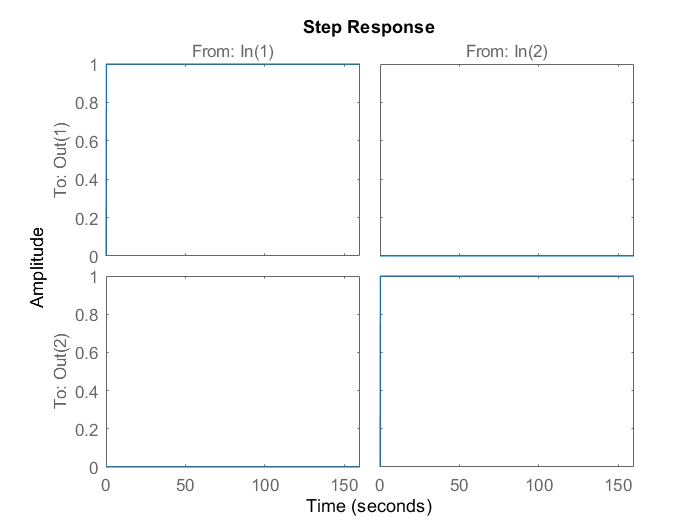

step(T_inv)

isstable(T_inv)

ans = logical
   1


Use margin to check performance of $L_{1,1}$:

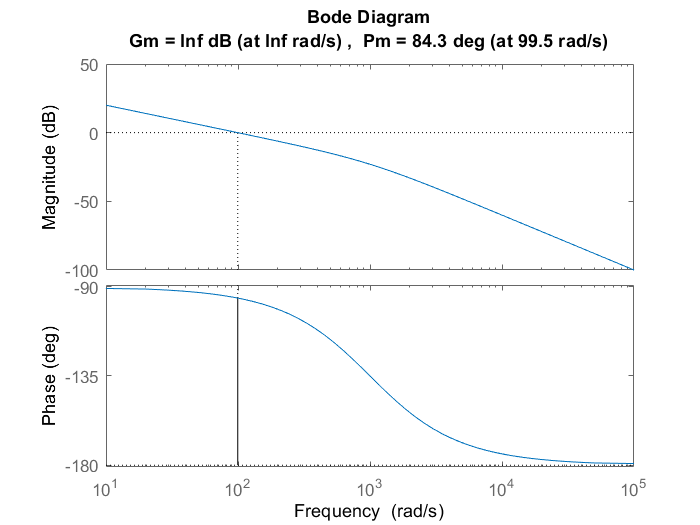

margin(L_inv(1,1));

The bode magnitude of sensitivity function:

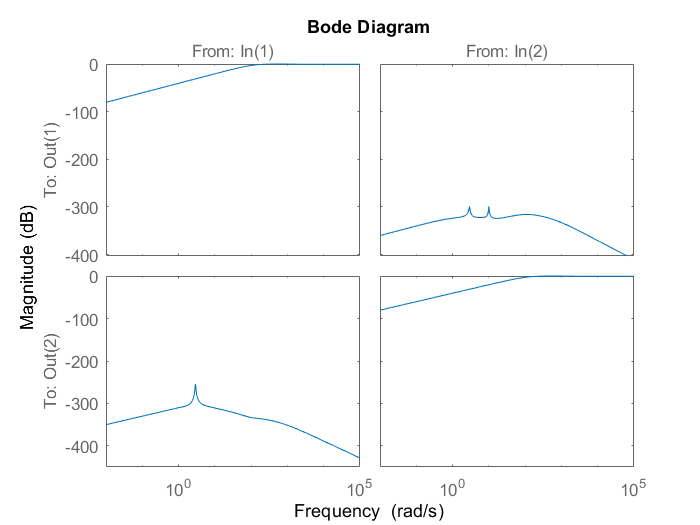

bodemag(S_inv)

Q(b)

M = 2;  
Mt = 1.5;
A = 1/1e3;  % reject disturbance by 1000
At = 1/1e3;

Wu = tf(1/100,1)*eye(2);
BW_right = 10^8*2*pi; 
BW_left = 0;
Wp = zeros(2);
Wt = zeros(2);
GAM_ms = 0;
while true
    GAM_old = GAM_ms;
    BW = (BW_left+BW_right)/2;
    BWt = 3*BW;
    Wp = makeweight(1/A,BW,1/M)*eye(2);  % 1st order
    Wt = makeweight(1/Mt,BWt,1/At)*eye(2);
    [K_ms,CL_ms,GAM_ms] = mixsyn(G,Wp,Wu,Wt);
    if abs(GAM_ms-GAM_old)<1e-6
        break
    elseif GAM_ms<1
        BW_left = BW;  
    else
        BW_right = BW;
    end
end

L_ms = G*K_ms;
T_ms = feedback(L_ms,eye(2));
S_ms = eye(2)-T_ms;

Save the iterative result:

save('P2Qb_results','Wp','Wt','Wu','K_ms','L_ms','T_ms','S_ms','GAM_ms');

Plot the magnitudes of $$$W_pS$$$, $W_tT$, and $W_uKS$:

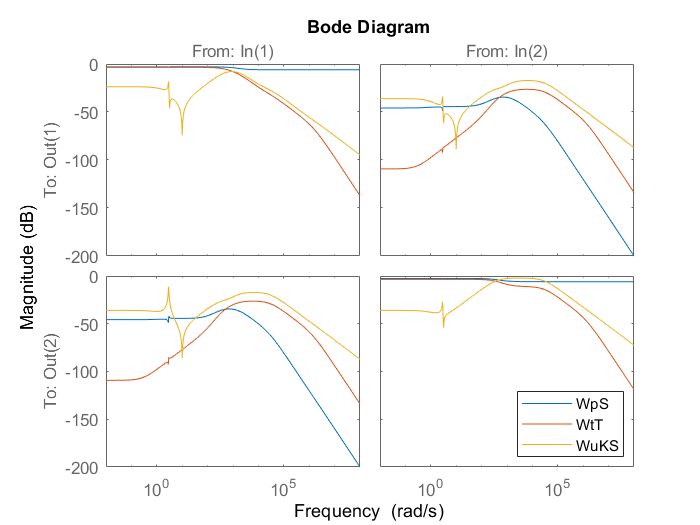

bodemag(Wp*S_ms, Wt*T_ms, Wu*K_ms*S_ms);
legend('WpS','WtT','WuKS','location','southeast')

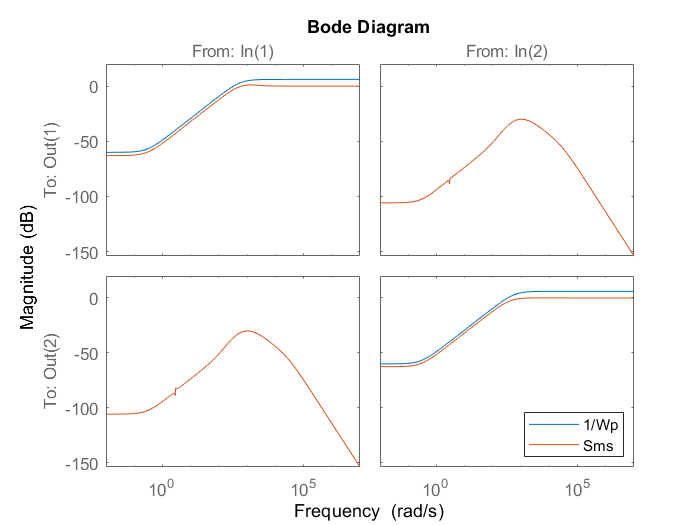

bodemag(eye/Wp,S_ms);
legend('1/Wp','Sms','location','southeast')

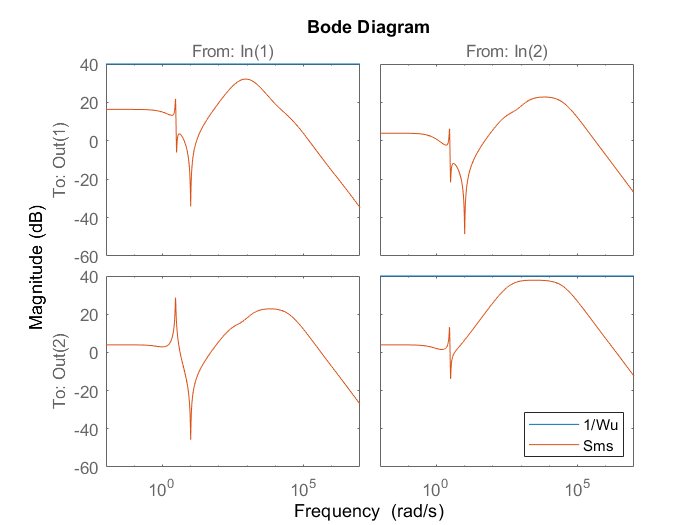

bodemag(eye/Wu,K_ms*S_ms);
legend('1/Wu','Sms','location','southeast')

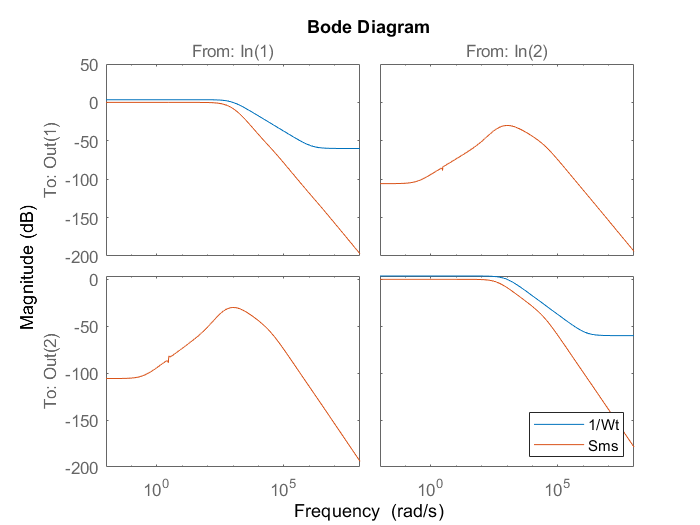

bodemag(eye/Wt,T_ms);
legend('1/Wt','Sms','location','southeast')

Problem 3

clear;clc

Q(a)

Assume the given system inside the dash line is $G^*
$.

Let the output of the generalized plant be:


$$\begin{cases}
z_1 = e_y = W_p(G^*u-Mr)\\
z_2 = e_u = W_uu
\end{cases}$$


Let the input of the generalied plant be:


$$\begin{cases}
w_1 = r\\
w_2 = n
\end{cases}$$


Let the output of the controller be $u$

Let the output of the controller be:


$$\begin{cases}
v_1 = r\\
v_2 = -G^*u-W_nn
\end{cases}$$


The generalized system $\left[\matrix{
z\cr  v
}\right] = P\left[\matrix{
w\cr u
}\right]$:


$$\left[\matrix{
z_1\cr z_2\cr v_1\cr v_2
}\right] = 
\left[\matrix{
-W_pM&0&W_pG^*\cr
0&0&W_u\cr
I&0&0\cr
0&-W_u&-G^*
}\right]
\left[\matrix{
w_1\cr w_2\cr u
}\right] \Rightarrow
P = 
\left[\matrix{
-W_pM&0&W_pG^*\cr
0&0&W_u\cr
I&0&0\cr
0&-W_u&-G^*
}\right]$$


Use linear fractional transformation to find N:


$$N = F_l(P,K) = P_{11}+P_{12}K(I-P_{22}K)^{-1}P_{21}$$


Where $P_{11} = \left[\matrix{-W_pM&0\cr 0&0}\right]$, $P_{12} = \left[\matrix{W_pG^*\cr 0}\right]$, $P_{21} = \left[\matrix{I&0\cr 0&-W_u}\right]$, $P_{22} = \left[\matrix{0\cr -G^*}\right]$

Assume all signals are single input or single output:

syms Wp M Gs Wu
P11 = [-Wp*M,0;0,0];
P12 = [Wp*Gs;0];
P21 = [1,0;0,-Wu];
P22 = [0;-Gs];
K = sym('K', [1,2]);
N = P11+P12*K/(1-P22*K)*P21;


$$N= \left[\matrix{-W_pM-W_p&-W_pW_u\cr 0&0}\right]$$


Q(b)

The DIDO system in Problem2:

s = tf('s');
G = [10*(s+2)/(s^2+0.2*s+100), 1/(s+5); 
    (s+2)/(s^2+0.1*s+10), 5*(s+1)/(s+2)/(s+3)];

Load previous results:

load('P2Qb_results')

Use sysic to generate generalized plant:

systemnames = 'G Wp Wu Wt';
inputvar = '[r{2};u{2}]';
outputvar = '[Wp;Wu;Wt;r-G]';
input_to_G = '[u]';
input_to_Wp = '[r-G]';
input_to_Wu = '[u]';
input_to_Wt = '[G]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;

Design controller based on the generalized mixed sensitivity plant and $H_{\infty}$ synthesis:

[K_hinf,CL_hinf,GAM_hinf] = hinfsyn(P,2,2);

Compare designed controller with mixsyn results:

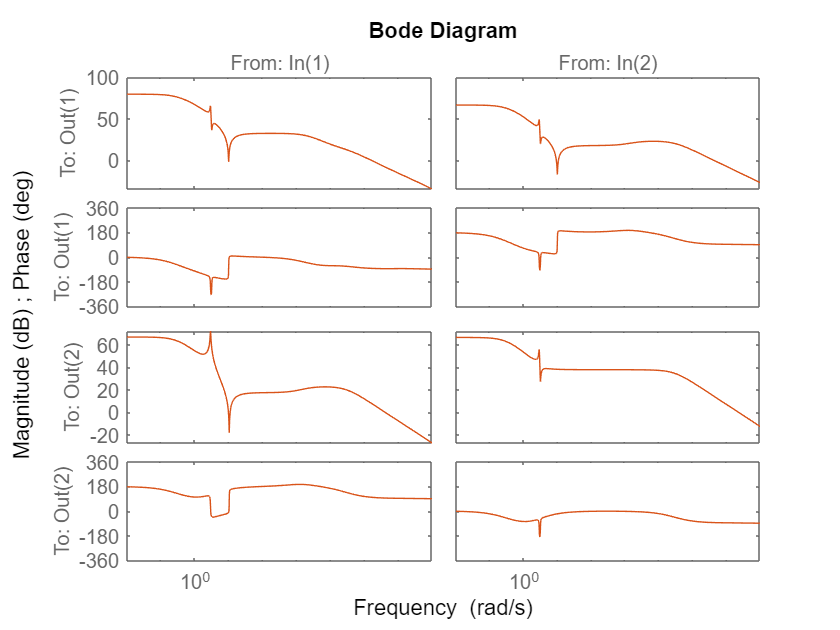

bode(K_hinf,K_ms);

Q(c)

 The linear fraction transformation:


$$F_l(H,\frac{1}{s})=H_{11}+H_{12}\frac{1}{s}(I-H_{22}\frac{1}{s})^{-1}H_{21}=H_{11}+\frac{H_{12}}{s}(sI-H_{22})^{-1}\frac{H_{21}}{s}$$


Let $F_l(H,\frac{1}{s})=C(sI-A)^{-1}B+D$:


$$\begin{cases}
H_{11}=D\\
H_{12} = C\\
H_{22} = A\\
H_{21} = B
\end{cases}
\Rightarrow 
H = \left[\matrix{D & C\cr B & A}\right]$$
